### Encryption and Decryption of IMAGE Using Fourier Matrices.

#### Encryption

inputImage = imread('C:\Users\blruc\OneDrive\Desktop\END\Mat\test.jpg');
inputImage = rgb2gray(inputImage);
transformedImage = fft2(inputImage);
keyMatrix = rand(size(transformedImage));
encryptedImage = transformedImage .* keyMatrix;
disp(keyMatrix)

  Columns 1 through 13

    0.8147    0.3445    0.8929    0.2834    0.7566    0.7750    0.7753    0.3118    0.3833    0.0396    0.2158    0.5351    0.1859
    0.9058    0.7805    0.7032    0.8962    0.9955    0.9142    0.6077    0.0553    0.7287    0.4694    0.0787    0.3984    0.2914
    0.1270    0.6753    0.5557    0.8266    0.9624    0.7826    0.9480    0.7538    0.8873    0.1501    0.9331    0.6705    0.4617
    0.9134    0.0067    0.1844    0.3900    0.5351    0.2955    0.0596    0.1319    0.0558    0.9913    0.6029    0.4405    0.3470
    0.6324    0.6022    0.2120    0.4979    0.9639    0.1518    0.2687    0.3559    0.1382    0.4271    0.3775    0.1329    0.3182
    0.0975    0.3868    0.0773    0.6948    0.1156    0.8479    0.9867    0.3959    0.8631    0.9554    0.6649    0.4392    0.4599
    0.2785    0.9160    0.9138    0.8344    0.0514    0.7849    0.7722    0.8855    0.4217    0.7242    0.7922    0.5476    0.2359
    0.5469    0.0012    0.7067    0.6096    0.3043    0.270

#### Decryption

decryptedImage = encryptedImage ./ keyMatrix;
recoveredImage = ifft2(decryptedImage);
recoveredImage = uint8(real(recoveredImage));

#### Results

disp("ORIGINAL_IMAGE")

ORIGINAL_IMAGE


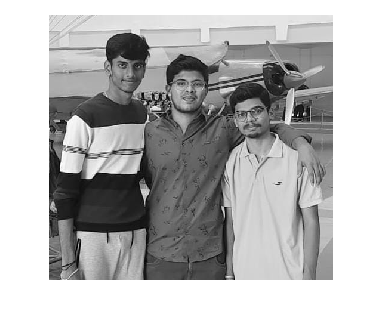

imshow(inputImage);

disp("Transfored Image using fft")

Transfored Image using fft


disp(transformedImage)

   1.0e+07 *

  Columns 1 through 6

   2.8408 + 0.0000i   0.1562 + 0.2143i  -0.1184 - 0.0015i  -0.0292 - 0.0996i  -0.0283 + 0.0952i  -0.0246 - 0.0099i
   0.2497 - 0.0408i  -0.2138 + 0.0377i  -0.0692 - 0.1413i   0.0069 - 0.0187i  -0.0403 + 0.0705i   0.0286 + 0.0108i
   0.2454 - 0.1492i   0.1018 - 0.0535i  -0.1033 - 0.0789i  -0.0638 + 0.0035i   0.0311 + 0.0037i  -0.0149 - 0.0494i
  -0.0458 - 0.0161i  -0.0114 + 0.1250i   0.0439 - 0.0128i  -0.0226 + 0.0360i   0.0005 - 0.0015i   0.0138 - 0.0274i
   0.0734 - 0.1105i   0.0170 - 0.0323i  -0.0179 - 0.0350i   0.0154 + 0.0619i  -0.0016 - 0.0158i  -0.0200 - 0.0140i
  -0.0296 - 0.1172i  -0.0527 + 0.0174i  -0.0232 - 0.0217i   0.0642 - 0.0199i  -0.0023 + 0.0015i  -0.0060 - 0.0062i
  -0.0110 - 0.0855i  -0.0055 + 0.0144i  -0.0094 + 0.0473i   0.0151 - 0.0221i   0.0170 - 0.0157i  -0.0002 + 0.0147i
   0.0645 - 0.0506i  -0.0094 - 0.0532i  -0.0019 - 0.0121i   0.0013 + 0.0158i  -0.0072 - 0.0170i   0.0038 - 0.0250i
  -0.0466 - 0.0408i  -0.0303 + 0.0434i   0.

disp("Encrypted Image Matrix")

Encrypted Image Matrix


disp(encryptedImage)

   1.0e+07 *

  Columns 1 through 6

   2.3145 + 0.0000i   0.0538 + 0.0738i  -0.1057 - 0.0014i  -0.0083 - 0.0282i  -0.0214 + 0.0720i  -0.0191 - 0.0076i
   0.2261 - 0.0369i  -0.1669 + 0.0295i  -0.0487 - 0.0994i   0.0062 - 0.0167i  -0.0401 + 0.0701i   0.0261 + 0.0099i
   0.0312 - 0.0189i   0.0687 - 0.0361i  -0.0574 - 0.0439i  -0.0528 + 0.0029i   0.0299 + 0.0035i  -0.0117 - 0.0387i
  -0.0419 - 0.0147i  -0.0001 + 0.0008i   0.0081 - 0.0024i  -0.0088 + 0.0140i   0.0003 - 0.0008i   0.0041 - 0.0081i
   0.0464 - 0.0699i   0.0102 - 0.0194i  -0.0038 - 0.0074i   0.0077 + 0.0308i  -0.0016 - 0.0152i  -0.0030 - 0.0021i
  -0.0029 - 0.0114i  -0.0204 + 0.0067i  -0.0018 - 0.0017i   0.0446 - 0.0138i  -0.0003 + 0.0002i  -0.0051 - 0.0052i
  -0.0031 - 0.0238i  -0.0050 + 0.0132i  -0.0086 + 0.0433i   0.0126 - 0.0184i   0.0009 - 0.0008i  -0.0002 + 0.0115i
   0.0353 - 0.0277i  -0.0000 - 0.0001i  -0.0013 - 0.0086i   0.0008 + 0.0097i  -0.0022 - 0.0052i   0.0010 - 0.0068i
  -0.0446 - 0.0390i  -0.0140 + 0.0201i   0.

disp("Decrypted Image")

Decrypted Image


imshow(recoveredImage);